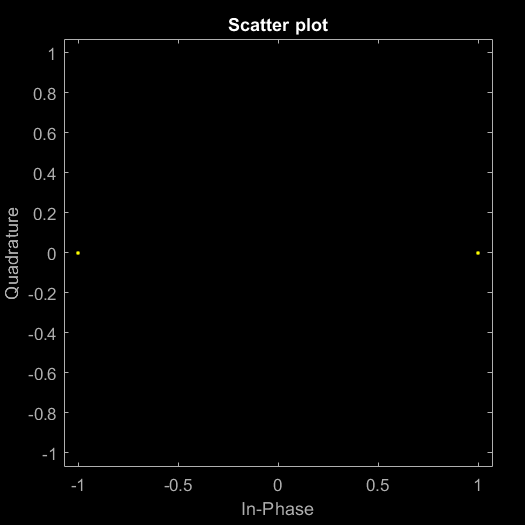

clc
clear all
N = 1000; %Data size 
Data = randi([0 1], 1,N); %Random data 
%BPSK MAPPING
for i=1:N
    if Data(i) == 0
        x(i) = -1;
    else
        x(i) = 1;
    end
end
scatterplot(x)

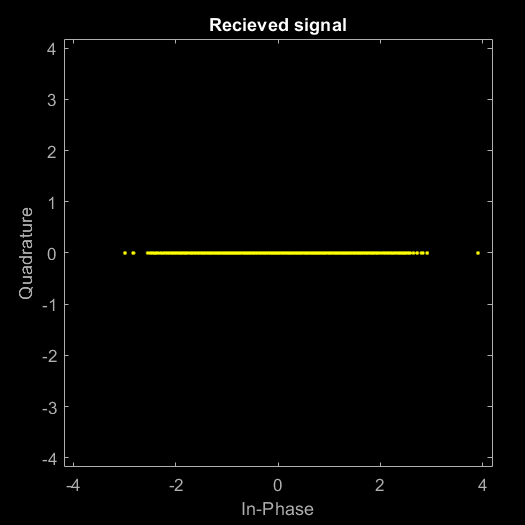

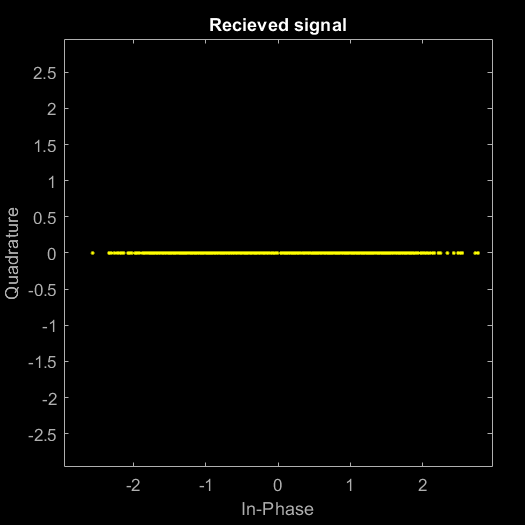

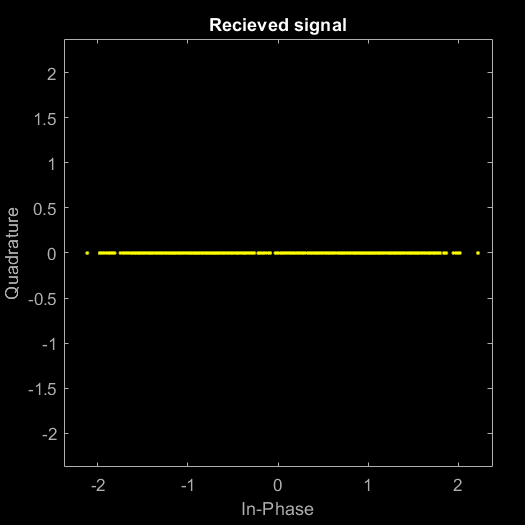

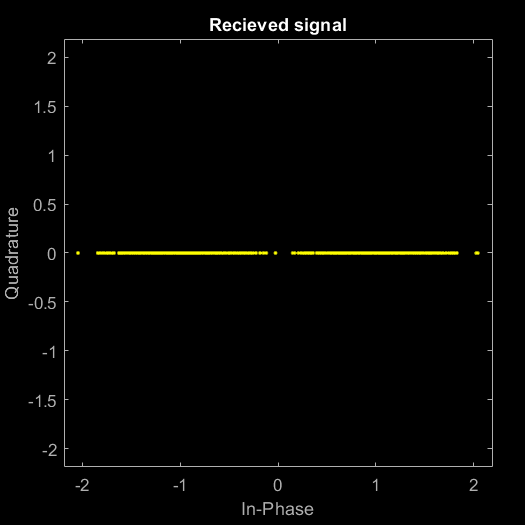

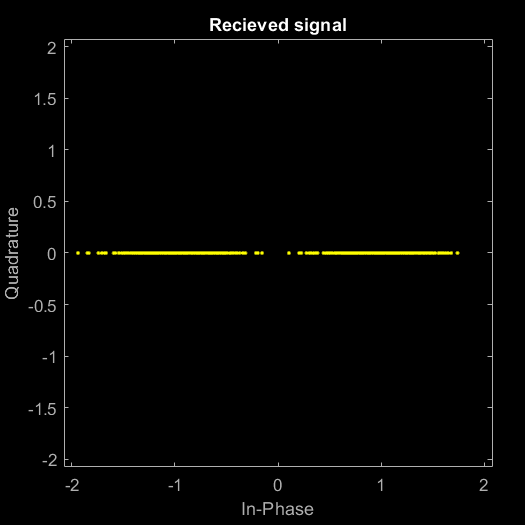

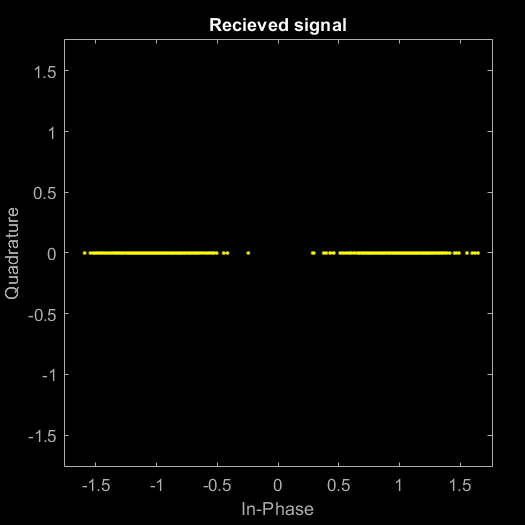

%AWGN CHANNEL 
BER_SIM = [];
for SNR = 0:2:10 
SNR_NORMAL = 10^(SNR/10); %IN NORMAL 
n = sqrt(1/(2*SNR_NORMAL))*randn(1,N);


%system model 
r = x+n; %Recieved signal
scatterplot(r);title("Recieved signal");
for i = 1:N
    if r(i)>0
        Data_cap = 1;
    else
        Data_cap = 0;
    end
end

%BER calculation 
[noe,ber] = biterr(Data,Data_cap);
BER_SIM = [BER_SIM ber];
end